%%清屏
clear;
close all;
clc;
%%第一步，定义状态空间矩阵
%%定义状态矩阵A，n*n矩阵
A=[1 0.1;-1 2];
n=size(A,1);

%%定义输入矩阵B,n*p矩阵
B=[0.2 1;0.5 2];
p=size(B,2);

%%定义Q矩阵，n*n矩阵
Q=[1 0;0 1];

%%定义F矩阵，n*n矩阵
F=[1 0;0 1];

%%定义R矩阵，p*p矩阵
R=[0.1 0;0 0.1];

%%定义step数量K
k_steps=100;

%%定义矩阵X_K，n*k矩阵
X_K=zeros(n,k_steps);

%%初始化状态变量，n*1向量
X_K(:,1)=[20;-20];

%%定义输入矩阵U_K，p*k矩阵
U_K=zeros(p,k_steps);

%%定义预测区间N
N=5;
%%Call MPC_Matrices函数 求得E,H矩阵
[E,H]=MPC_Matrices(A,B,Q,R,F,N);

%%计算每一步的状态变量的值 
for k=1:k_steps
    %%求得U_K(:,k)
    U_K(:,k)=Prediction(X_K(:,k),E,H,N,p);
    %计算第k+1步时状态变量的值
    X_K(:,k+1)=(A*X_K(:,k)+B*U_K(:,k));
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


%%绘制状态变量和输入的变化
subplot(2,1,1);hold;

已锁定最新绘图


for i=1:size(X_K,1)
    plot(X_K(i,:));
end
legend("x1","x2")
hold off;

subplot(2,1,2);hold;

已锁定最新绘图


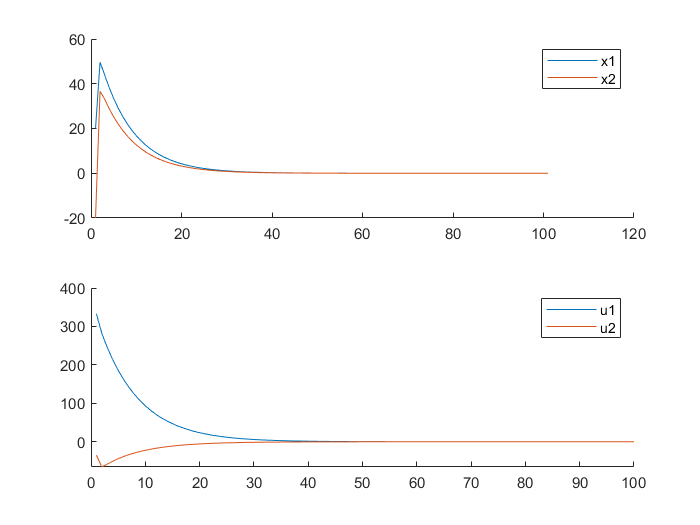

for i=1:size(U_K,1)
    plot(U_K(i,:));
end
legend("u1","u2")